# Basic OFDM

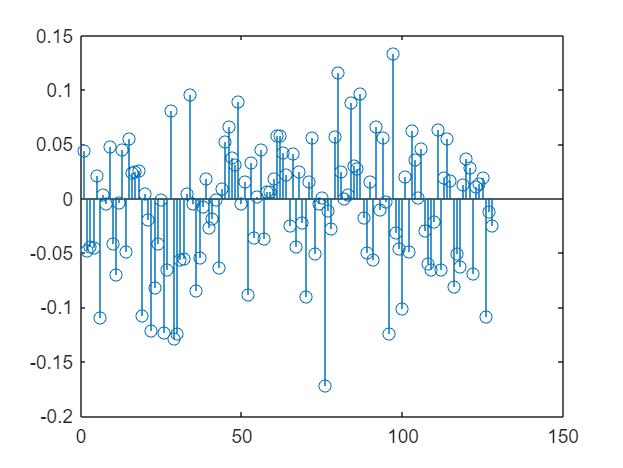


% https://www.mathworks.com/help/comm/gs/basic-ofdm-with-no-cyclic-prefix.html
% OFDM simultaneously transmits closely spaced orthogonal subcarrier signals of overlapping sinusoids

bps = 4;    % Bits per symbol
M = 2^bps;  % 16QAM
nFFT = 128; % Number of FFT bins

txsymbols = randi([0 M-1],nFFT,1);%128x1
txgrid = qammod(txsymbols,M,UnitAveragePower=true);%128x1 complex
txout = ifft(txgrid,nFFT);
stem(1:nFFT,real(txout))

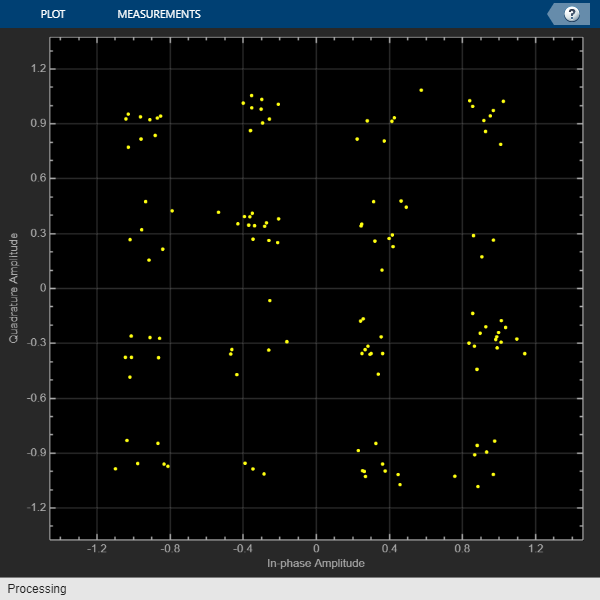


%Filter the transmission data through an AWGN channel with minimal noise.
rxin = awgn(txout,40);
rxgrid = fft(rxin,nFFT);
%Plot the constellation diagram.
cd = comm.ConstellationDiagram('ShowReferenceConstellation',false);
cd(rxgrid)


rxsymbols = qamdemod(rxgrid,M,UnitAveragePower=true);
if isequal(txsymbols,rxsymbols)
    disp("Recovered symbols match the transmitted symbols.")
else
    disp("Recovered symbols do not match transmitted symbols.")
end

Recovered symbols match the transmitted symbols.


## OFDM

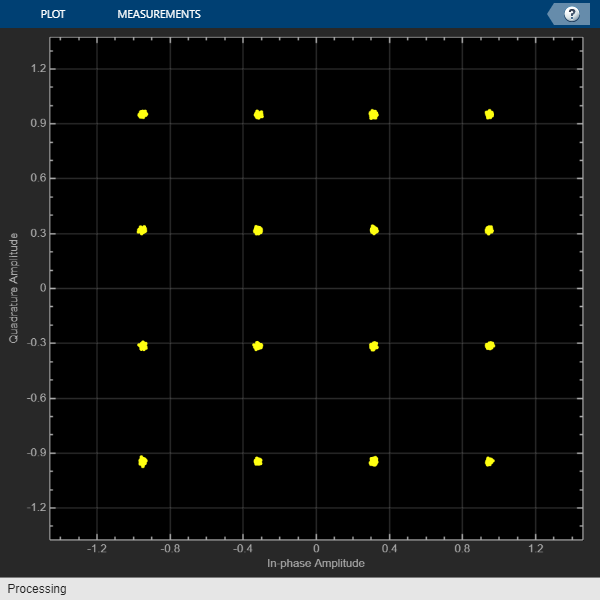

% Setting up variables and system parameters:
N = 64; % size of the IFFT block available at Tx
M = 68; % number of OFDM symbols in a transmit frame
modOrder = 16; % order of the modulation scheme being used
bitsPerSymbol = log2(modOrder); % the number of bits each symbol will represent...
numBits = (N/2 - 1)*(M)*(bitsPerSymbol); % the amount (or length) of the data we should generate...
txBits = randi([0 1], numBits, 1); % our data bit stream
constellationValues = (0:modOrder-1)'; % the value of the constellation (in decimal)

modulatedData = qammod(txBits, modOrder, "InputType", "bit", "UnitAveragePower", true);     

Ftx = zeros(N, M); % 64x68 the transmit frame (empty at the moment)

% Now to form the transmit frame:
Ftx(2:N/2, :) = reshape(modulatedData, N/2-1, M);
Ftx(N/2+2:end, :) = conj(flip(Ftx(2:N/2, :), 1));

G = 0; % the fraction of a symbol that will be used as the cyclic prefix...
cpLen = G*N; % the cyclic prefix length...

ofdmSymbols = ifft(Ftx); % taking the IFFT of each column of Ftx...
ofdmSymbols = [ofdmSymbols(end-cpLen+1:end, :); ofdmSymbols]; % adding the CP to each symbol

% Now to form the transmit sequence (s). This is got by
% concatenating all the OFDM symbols together:
s = ofdmSymbols(:); % the transmit sequence (s)

channelSNR = 40; % the channel's signal-to-noise ratio...

r = awgn(s, channelSNR, "measured");

ofdmSymbolsReceived = reshape(r, N+cpLen, M);

% Now we can remove the cyclic prefix from each of the symbols:
ofdmSymbolsReceived = ofdmSymbolsReceived(cpLen+1:end, :);

% Now we take the FFT of each symbol... this will form the received frame:
Frx = fft(ofdmSymbolsReceived);

payloadData = Frx(2:N/2, :); % extracting the payload from the frame...

%Plot the constellation diagram.
cd = comm.ConstellationDiagram('ShowReferenceConstellation',false);
cd(payloadData(:))


% Now we must demodulate the received symbols in order to get back the
% bits:
rxBits = qamdemod(payloadData(:), modOrder, "OutputType", "bit", "UnitAveragePower", true);

% We can work out the number of the bit errors by comparing the bit stream
% that was sent out and the bit stream that was received. When two vectors
% are compared using the "==" operator, the result is a "logical" vector
% made up of 1s and 0s. We can use this idea to compare the received bits
% (rxBits) with the transmitted ones (txBits):
numBitErrors = numBits - sum(rxBits == txBits);
numBitErrors

numBitErrors = 0


BER = numBitErrors/numBits; % the bit error rate (BER)
BER

BER = 0